#  Machine Learning with MATLAB

Digital Twin & Automation

# Linear Regression

## Example 1: Fit with Linear Regression 

**Data Acquisition**

- Feature: One-Dimension,  p=1

- True value: ytrue = 2X+3

x = randn(100,1);
y = x*2 + 3+randn(100,1);

**Fit Linear Regression**

mdl = fitlm(x,y)

mdl = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)      3.331     0.089185    37.349    9.1472e-60
    x1              1.8815     0.087178    21.583    5.1341e-39


관측값 개수: 100, 오차 자유도: 98
RMS 오차: 0.89
결정계수: 0.826, 수정된 결정계수: 0.824
상수 모델에 대한 F-통계량: 466, p-값 = 5.13e-39

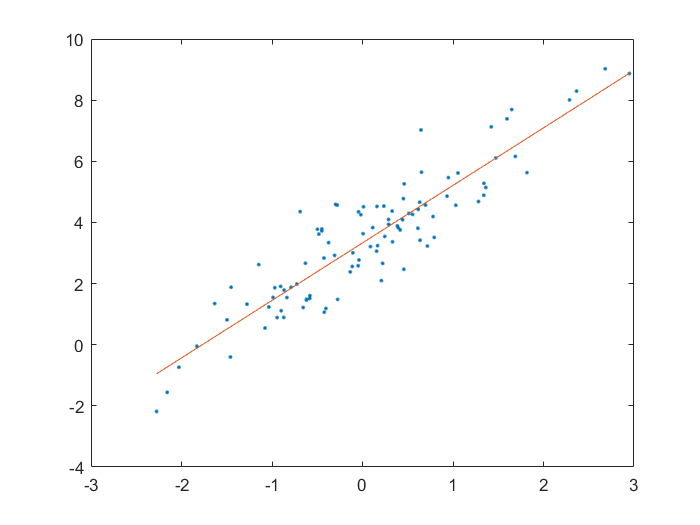


% Plot prediction
plot(x,y,'.',x,mdl.Fitted, '-')

**Anlayze Linear Regression**

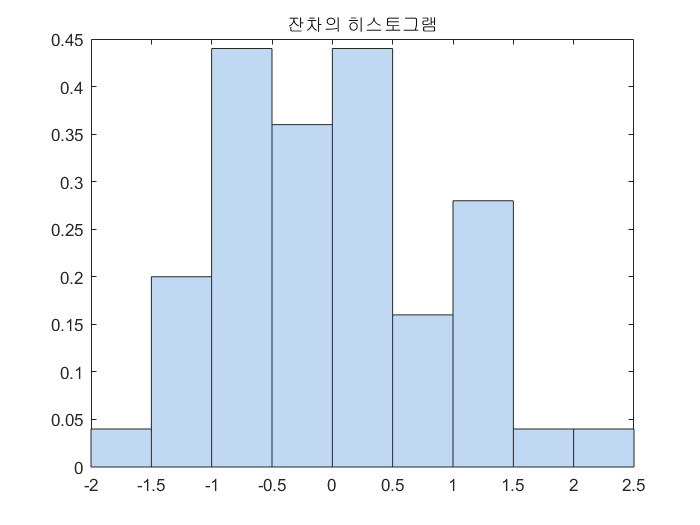

% Plot residual histogram
plotResiduals(mdl)


% From remove outlier from histogram
outl = find(abs(mdl.Residuals.Raw) > 2);
mdl.Residuals.Raw(outl)

ans =     2.3179
    2.4749



% Fit with outlier removed
mdl2 = fitlm(x,y,'Exclude',outl)

mdl2 = 선형 회귀 모델:
    y ~ 1 + x1

추정된 계수:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     3.2819     0.083877    39.128    8.4123e-61
    x1              1.8842     0.081513    23.115    5.1921e-41


관측값 개수: 98, 오차 자유도: 96
RMS 오차: 0.829
결정계수: 0.848, 수정된 결정계수: 0.846
상수 모델에 대한 F-통계량: 534, p-값 = 5.19e-41

**Predict with Test data**

% Ypredict and confidence interval
Xnew=2;
% y=7 %true
[Ynew,YnewI]=predict(mdl2,Xnew)

Ynew = 7.0503

YnewI =     6.6949    7.4056


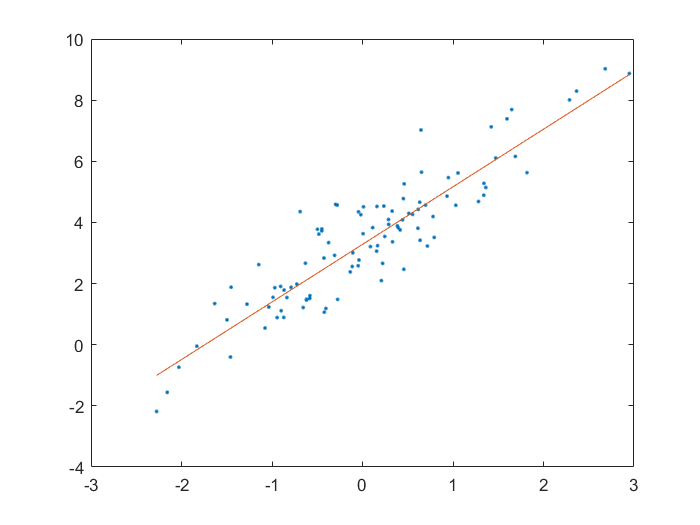


% Plot prediction
plot(x,y,'.',x,mdl2.Fitted, '-')

## Example 2: Predict Car MPG

Find linear relationship of  MPG(연비) with   Weight & Displacement

Then, Predict MPG for a car with Weight=3000 , Displacement=300

**Data Acquisition**

-  Dependet Variable:  MPG

- Independet Variables: Weight, Displacement

clear
load carsmall

tbl = table(MPG,Weight, Displacement);  % table type

**Fit  Linear Regression**

mdl = fitlm(tbl,'MPG~Weight+Displacement')

mdl = 선형 회귀 모델:
    MPG ~ 1 + Weight + Displacement

추정된 계수:
                     Estimate        SE         tStat       pValue  
                    __________    _________    _______    __________

    (Intercept)         46.925       2.0858     22.497    6.0509e-39
    Weight          -0.0068422    0.0011337    -6.0353    3.3838e-08
    Displacement     -0.014593    0.0082695    -1.7647      0.080968


관측값 개수: 94, 오차 자유도: 91
RMS 오차: 4.09
결정계수: 0.747, 수정된 결정계수: 0.741
상수 모델에 대한 F-통계량: 134, p-값 = 7.22e-28

%goodness of fit
%

mdl.CoefficientNames

ans = 1×3 cell 배열
    {'(Intercept)'}    {'Weight'}    {'Displacement'}


mdl.Coefficients.Estimate

ans =    46.9247
   -0.0068
   -0.0146


**Analyze, Modify**

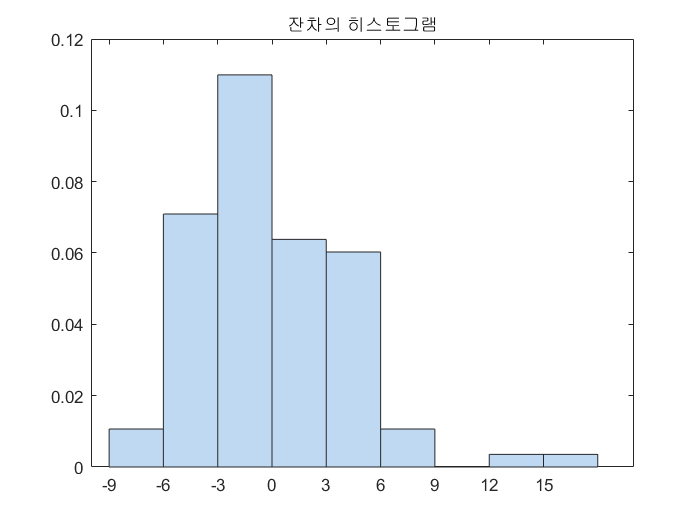

plotResiduals(mdl)


% Remove outlier
outl = find((mdl.Residuals.Raw) > 9);

% Fit with outlier removed
mdl2 = fitlm(tbl,'MPG~Weight+Displacement','Exclude',outl)

mdl2 = 선형 회귀 모델:
    MPG ~ 1 + Weight + Displacement

추정된 계수:
                     Estimate         SE         tStat       pValue  
                    __________    __________    _______    __________

    (Intercept)         45.548        1.8056     25.226    2.5559e-42
    Weight          -0.0062503    0.00097845    -6.3879    7.4767e-09
    Displacement     -0.018035     0.0071414    -2.5255      0.013324


관측값 개수: 92, 오차 자유도: 89
RMS 오차: 3.51
결정계수: 0.796, 수정된 결정계수: 0.792
상수 모델에 대한 F-통계량: 174, p-값 = 1.78e-31

mdl2.Coefficients.Estimate

ans =    45.5477
   -0.0063
   -0.0180


**Predict**

Detailed look at the interactions 

% Ypredict and confidence interval
Xnew=[3000 300]; 
[Ynew,YnewI]=predict(mdl2,Xnew)

Ynew = 21.3863

YnewI =    19.8515   22.9211


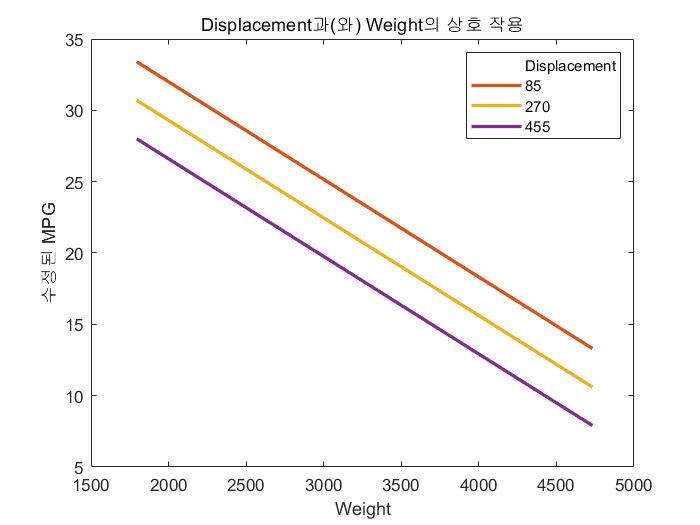


plotInteraction(mdl,'Displacement','Weight','predictions')

# Exercise

## Exercise 1 :  Using Gradient Descent

**Linear Regression Using Gradient Descent**

Hypothesis. 

To find the parameters, repeat until convergence

where

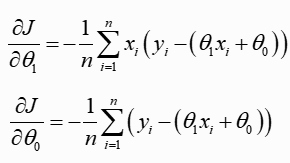

**Data Acquisition**

Feature: One-Dimension,  p=1

True: y = 2X+3

N=100;
X = randn(N,1);
Y = X*2 + 3+randn(N,1);



**Fit Linear Regression:  Gradient Descent**

% dJ/dx
lamda=0.1  % learning rate

lamda = 0.1000


% Initialization for t0, t1
t0=0.5;
t1=0.5;
e=1;
itrN=1000;
k=0

k = 0


%%% ADD your code here
while(e>0.001 || k<itrN)
     h= t1*X + t0;
     dJt1= sum(X.*(Y-h))/N * -1;
     dJt0= sum((Y-h))/N * -1;
     t1_new= t1 - lamda * dJt1; 
     t0_new= t0 - lamda * dJt0;
    e=0.5*(abs((t1_new-t1))+abs((t0_new-t0)));
    t1=t1_new;
    t0=t0_new;
    k=k+1;
end


% Predicted hypothesis y(x)
ypred = t1*X + t0; %%% ADD your code here


disp('optimal paraterms are')

optimal paraterms are


t1

t1 = 2.0133

t0

t0 = 2.9729

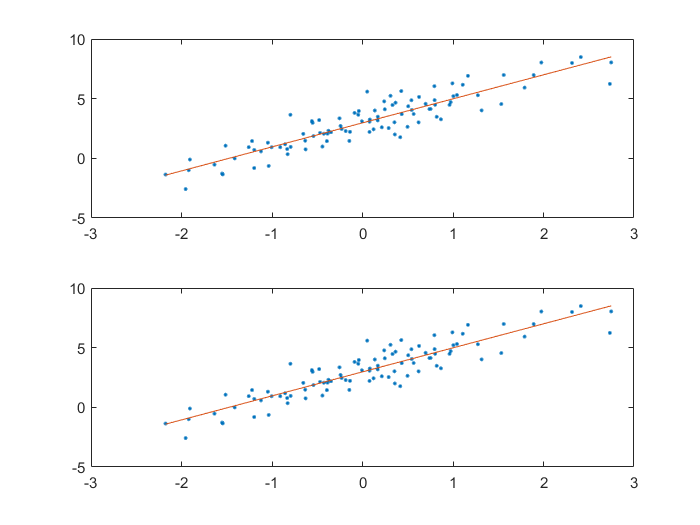



% MATLAB fit linear 
mdl = fitlm(X,Y);   %%% ADD your code here


% Plot and compare predictions
figure
subplot(2,1,1)
plot(X,Y,'.',X,mdl.Fitted, '-')
subplot(2,1,2)
plot(X,Y,'.',X,ypred, '-')

## Exercise 2 :  Linear Regression with p=2

Find the linear regression. Remove Outlier and predict a test value Xtest=[2;1];.  You can use MATLAB fitlm()

- Feature: 2-Dimensions,  p=2

- True value: y = 2*X1+4*X2+3

**Data Acquisition**

X_ex2 = randn(100,2);
Y_ex2 = X_ex2*[2;4] + 3+ randn(100,1);

% Your code goes here
% Your code goes here

**Fit  Linear Regression**

mdl_ex2 = fitlm(X_ex2,Y_ex2)

mdl_ex2 = 선형 회귀 모델:
    y ~ 1 + x1 + x2

추정된 계수:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)     3.1084     0.10275    30.252    3.4011e-51
    x1              1.9417     0.10341    18.777    4.5389e-34
    x2              4.0586     0.10137    40.038    3.9944e-62


관측값 개수: 100, 오차 자유도: 97
RMS 오차: 1.02
결정계수: 0.957, 수정된 결정계수: 0.956
상수 모델에 대한 F-통계량: 1.07e+03, p-값 = 8.68e-67

**Analyze, Modify**

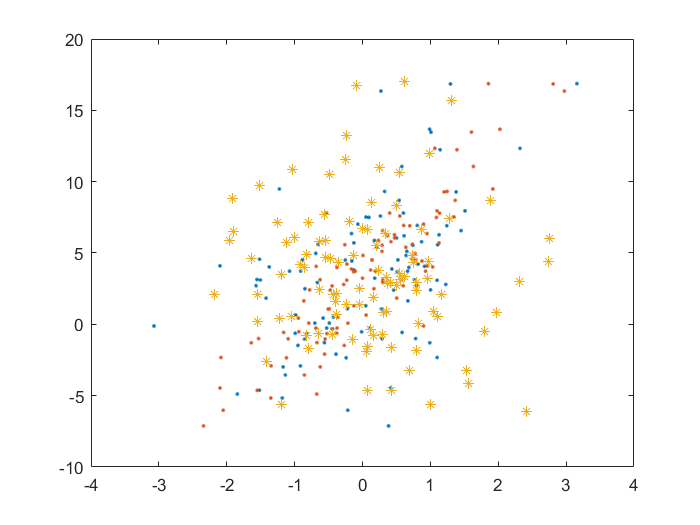

%plot 
figure
plot(X_ex2,Y_ex2,'.', X,mdl_ex2.Fitted,'*')

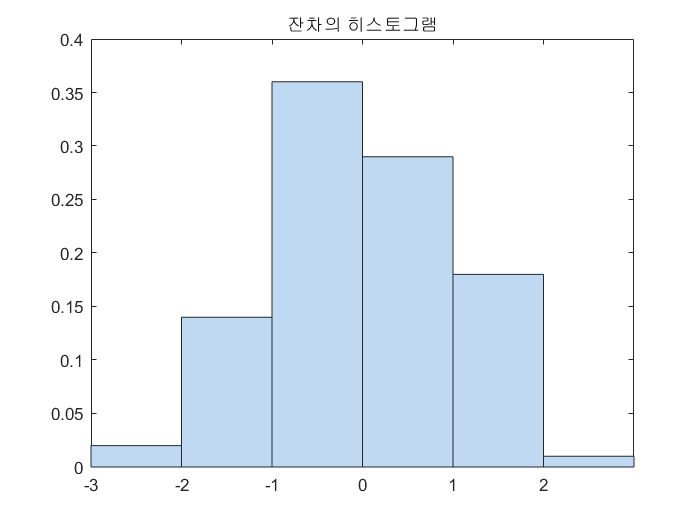


% Remove outlier
figure
plotResiduals(mdl_ex2)


outl_ex2 = find(abs(mdl_ex2.Residuals.Raw) > 2);   % 2보다 큰 data는 outlier로 간주
mdl_ex2.Residuals.Raw(outl_ex2)

ans =     2.2864
   -2.5500
   -2.1753



% Fit with outlier removed
mdl2_ex2 = fitlm(X_ex2,Y_ex2,'Exclude',outl_ex2)

mdl2_ex2 = 선형 회귀 모델:
    y ~ 1 + x1 + x2

추정된 계수:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)     3.1299     0.096865    32.312    1.0716e-52
    x1              1.9837     0.097122    20.425    2.4656e-36
    x2              4.0901     0.095043    43.034    1.1813e-63


관측값 개수: 97, 오차 자유도: 94
RMS 오차: 0.949
결정계수: 0.963, 수정된 결정계수: 0.962
상수 모델에 대한 F-통계량: 1.22e+03, p-값 = 6.68e-68

**Predict**

Predict for a Test value

Xnew_ex2=[2,4];
[Ynew,YnewI]=predict(mdl2_ex2,Xnew_ex2)

Ynew = 23.4577

YnewI =    22.6341   24.2813


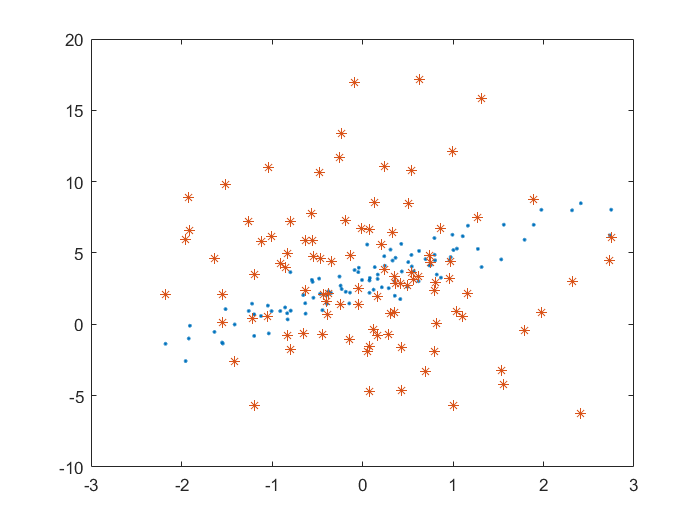


% Plot prediction
plot(X,Y,'.', X,mdl2_ex2.Fitted,'*')

## Exercise 3:  Linear Regression with p=4

Find linear relationship of 

- MPG ~ 1 + Acceleration + Displacement + Horsepower + Weight 

Choose a test data and predict

**Data Acquisition**

% load carsmall
clear; clc; 
load carsmall

tbl = table(MPG,Acceleration,Displacement,Horsepower,Weight);  % table type

**Fit  Linear Regression**


mdl_ex3 = fitlm(tbl,'MPG~Acceleration+Displacement+Horsepower+Weight')

mdl_ex3 = 선형 회귀 모델:
    MPG ~ 1 + Acceleration + Displacement + Horsepower + Weight

추정된 계수:
                     Estimate        SE         tStat        pValue  
                    __________    _________    ________    __________

    (Intercept)         48.117       3.9008      12.335    6.9194e-21
    Acceleration     -0.060312      0.21167    -0.28493       0.77636
    Displacement    -0.0066826     0.011594    -0.57638       0.56583
    Horsepower       -0.037547     0.026139     -1.4364       0.15442
    Weight           -0.006084    0.0013823     -4.4014      3.01e-05


관측값 개수: 93, 오차 자유도: 88
RMS 오차: 4.11
결정계수: 0.753, 수정된 결정계수: 0.742
상수 모델에 대한 F-통계량: 67.1, p-값 = 6.49e-26

mdl_ex3.CoefficientNames

ans = 1×5 cell 배열
    {'(Intercept)'}    {'Acceleration'}    {'Displacement'}    {'Horsepower'}    {'Weight'}


mdl_ex3.Coefficients.Estimate

ans =    48.1175
   -0.0603
   -0.0067
   -0.0375
   -0.0061


**Analyze, Modify**

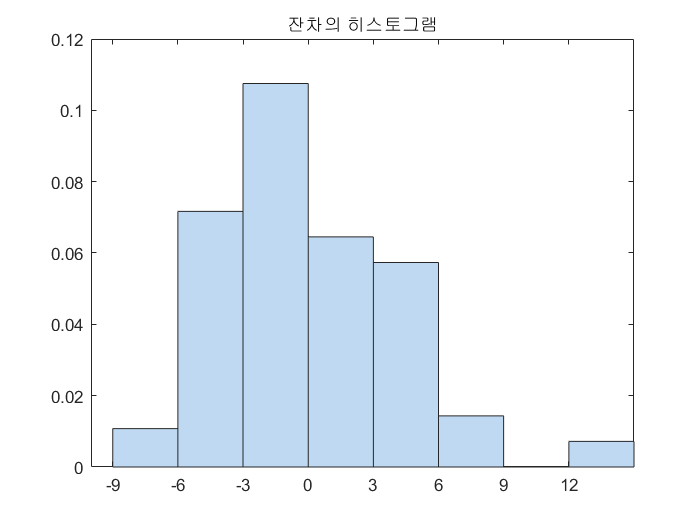

% Remove outlier
plotResiduals(mdl_ex3)

% Remove outlier
outl_ex3 = find((mdl_ex3.Residuals.Raw) > 9);

% Fit with outlier removed
mdl2_ex3 = fitlm(tbl,'MPG~Acceleration+Displacement+Horsepower+Weight','Exclude',outl_ex3)

mdl2_ex3 = 선형 회귀 모델:
    MPG ~ 1 + Acceleration + Displacement + Horsepower + Weight

추정된 계수:
                     Estimate        SE         tStat       pValue  
                    __________    _________    _______    __________

    (Intercept)         52.278       3.4049     15.354    2.2896e-26
    Acceleration      -0.44717      0.19284    -2.3189      0.022774
    Displacement     -0.027687     0.010354     -2.674      0.008968
    Horsepower       -0.023844     0.022474    -1.0609       0.29169
    Weight          -0.0047039    0.0011924    -3.9449    0.00016242


관측값 개수: 91, 오차 자유도: 86
RMS 오차: 3.46
결정계수: 0.809, 수정된 결정계수: 0.8
상수 모델에 대한 F-통계량: 90.8, p-값 = 4.83e-30

mdl2_ex3.Coefficients.Estimate

ans =    52.2780
   -0.4472
   -0.0277
   -0.0238
   -0.0047


**Predict**

Predict for a Test value

% Ypredict and confidence interval
Xnew=[3000 300 300 3000]; 
[Ynew,YnewI]=predict(mdl2_ex3,Xnew)

Ynew = -1.3188e+03

YnewI = 	1.0e+03 *

   -2.4671   -0.1705


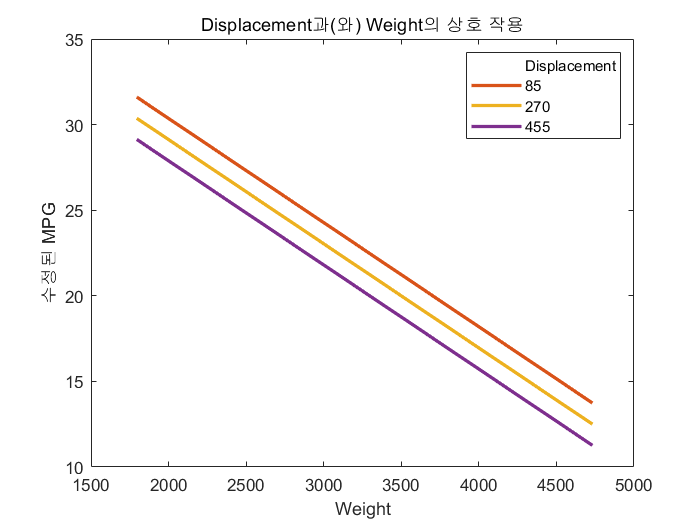

plotInteraction(mdl_ex3,'Displacement','Weight','predictions')